ttRaw = importTaxiDataWithoutCleaning("yellow_tripdata_2015-06.csv");

fareLessThan0 = height(ttRaw(ttRaw.Fare<=0,:))/height(ttRaw)*100

fareLessThan0 = 0.0637

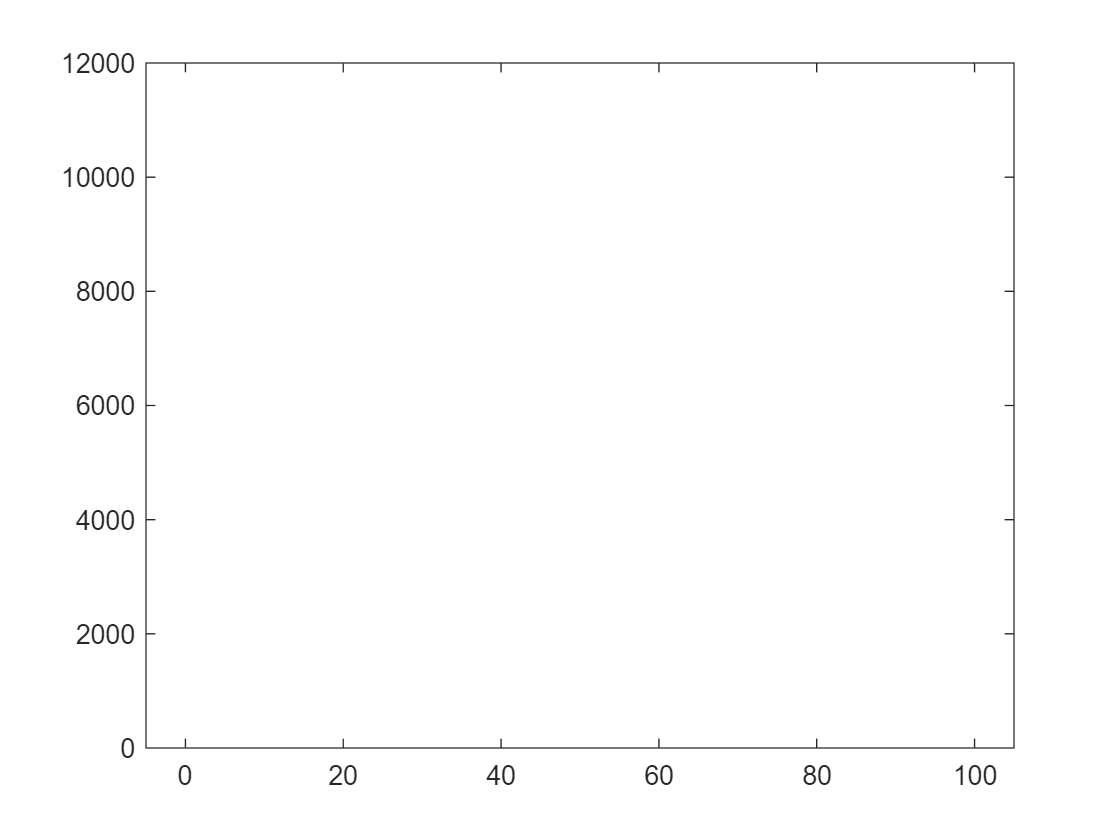

s = summary(ttRaw);
histogram(ttRaw.TotalCharge(ttRaw.TotalCharge>0 & ttRaw.TotalCharge<100))

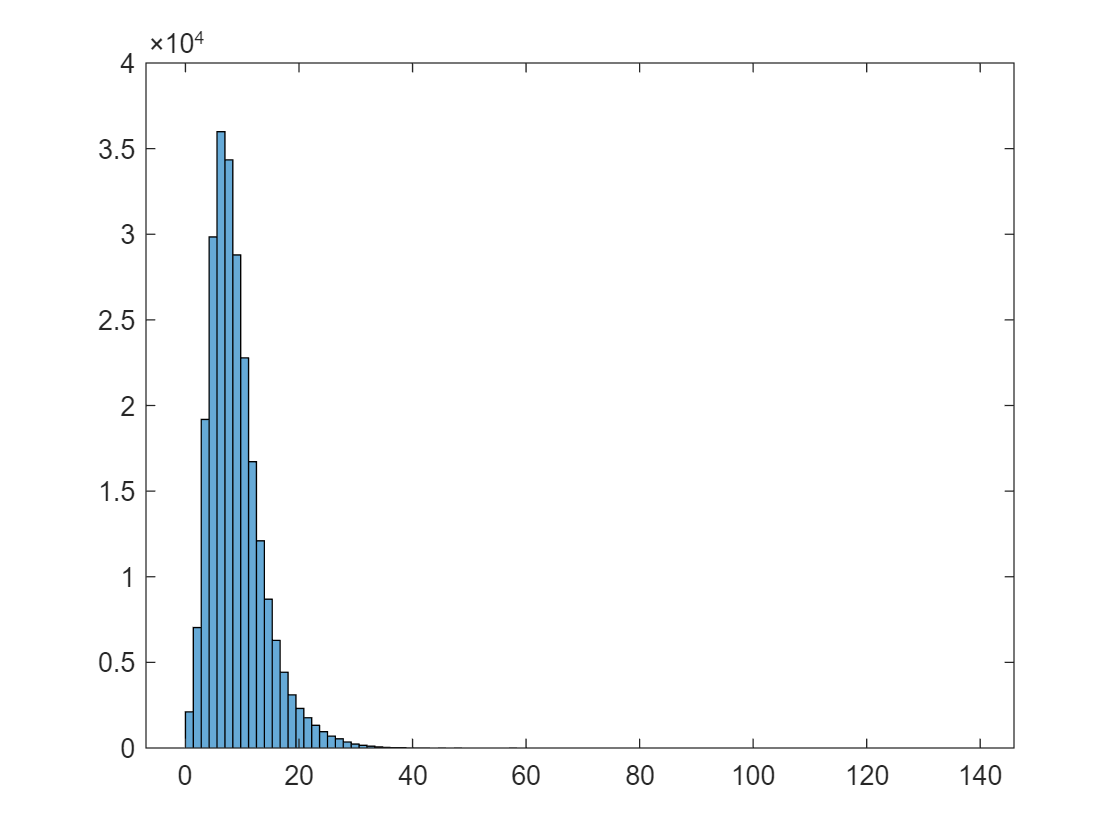

taxiData = 255761×22 table
    Vendor        PickupTime             DropoffTime        Passengers    Distance    PickupLon    PickupLat    RateCode    HeldFlag    DropoffLon    DropoffLat      PayType      Fare    ExtraCharge    Tax    Tip     Tolls    ImpSurcharge    TotalCharge    Duration    AveSpeed    TimeOfDay
    ______    ___________________    ___________________    __________    ________    _________    _________    ________    ________    __________<

ttClean = importTaxiData("yellow_tripdata_2015-06.csv");
ttClean = addCrowDistance(ttClean);
histogram(ttClean.CrowDistance./(ttClean.Duration/60),100)